# Low code time series and geospatial data handling, analysis and visualization

## Download data from Kaggle: [https://www.kaggle.com/datasets/decide-soluciones/air-quality-madrid](https://www.kaggle.com/datasets/decide-soluciones/air-quality-madrid)  

- madrid_2018.csv

- stations.csv

## Use the Import Data App to 

### import "madrid_2018.csv", then preview the File

# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 16-Jul-2025 14:20:46

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 16);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["date", "BEN", "CH4", "CO", "EBE", "NMHC", "NO", "NO_2", "NOx", "O_3", "PM10", "PM25", "SO_2", "TCH", "TOL", "station"];
opts.SelectedVariableNames = ["date", "CH4", "CO", "NO", "NO_2", "station"];
opts.VariableTypes = ["datetime", "string", "double", "double", "string", "string", "double", "double", "string", "string", "string", "string", "string", "string", "string", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["BEN", "EBE", "NMHC", "NOx", "O_3", "PM10", "PM25", "SO_2", "TCH", "TOL"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["BEN", "EBE", "NMHC", "NOx", "O_3", "PM10", "PM25", "SO_2", "TCH", "TOL"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "date", "InputFormat", "yyyy-MM-dd HH:mm:ss", "DatetimeFormat", "preserveinput");

% Import the data
madrid_2018 = readtimetable("YourFolderPath\madrid_2018.csv",opts,"RowTimes","date");

madrid_2018.station = categorical(madrid_2018.station);
madrid_2018 = sortrows(madrid_2018, "date")

madrid_2018 = 69096×5 timetable
           date            CH4     CO     NO    NO_2    station 
    ___________________    ____    ___    __    ____    ________

    2018-01-01 01:00:00     NaN    0.3     2     15     28079004
    2018-01-01 01:00:00    1.38    0.2     6     33     28079008
    2018-01-01 01:00:00     NaN    NaN     3     11     28079011
    2018-01-01 01:00:00     NaN    0.2     1     12     28079016
    2018-01-01 01:00:00     NaN    NaN     6     23     28079017
    2018-01-01 01:00:00     NaN    0.6    63     32     28079018
    2018-01-01 01:00:00    1.11    0.2     1      1     28079024
    2018-01-01 01:00:00     NaN    NaN    

## Clear temporary variables

clear opts


## Unstack Table Variable

% Unstack variables
NO = unstack(madrid_2018,"NO","station",AggregationFunction=@mean, ...
    VariableNamingRule="preserve")

## Clean Missing Data

% Fill missing data
[NO_new,missingIndices] = fillmissing(NO,"linear");

% Display results
figure

% Plot cleaned data
plot(NO.date,NO_new.("28079011"),SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Cleaned data")
hold on

% Plot filled missing entries
plot(NO.date(missingIndices(:,3)),NO_new.("28079011")(missingIndices(:,3)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,3)))

hold off
legend
ylabel("28079011")
xlabel("date")
clear missingIndices

## Check out the stations location

### import "stations.csv", then preview the File

Transform the "id" variable from *Double *to *String*


stations.id = string(stations.id)

Unable to resolve the name 'stations.id'.

### Create a Plot - to plot the Stations on a map

% Create geoscatter of stations.lat and stations.lon
S = geoscatter(stations.lat,stations.lon,[],stations.elevation,"filled");
colorbar
colormap("hot")
% Add title
title("stations.lat vs. stations.lon")

## Change the geobasemap and fill the circles 

Ask [MATLAB GPT](https://chatgpt.com/g/g-QFTjbeK3U-matlab) or [MATLAB AI Chat Playground](https://uk.mathworks.com/matlabcentral/playground/new) to "change the format of degrees in the geographic plot"

(check the documentation!)

geobasemap("satellite")
geotickformat("-dd")

## Ask Copilot how to add station labels

"Can you add in the figure the text label (id) for the stations? Don't use a for loop"

`(Make sure "lat" is the first argument and "lon" the second one!!)`

% Add text labels for the stations
text(stations.lat, stations.lon, stations.id, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 8);

Add a Colorbar (you can import a colormap from the IPCC [Standard-Climate-Colormaps-for-MATLAB - File Exchange - MATLAB Central](https://uk.mathworks.com/matlabcentral/fileexchange/180750-standard-climate-colormaps-for-matlab))

cmap = uint8(readmatrix("misc_seq_2.txt"));
colorbar
colormap(cmap)

## BONUS! Launch and Explore the "signalAnalyzer" App

 NO_values = NO_new.("28079008");     % input data for signal analyzer
 signalAnalyzer

## You can now Try:

### Smooth Data

% Smooth input data
[newTable,winSize] = smoothdata(NO_new,"gaussian",days(1));

% Display results
figure
plot(NO_new.date,NO_new.("28079004"),SeriesIndex=6,DisplayName="Input data")
hold on
plot(NO_new.date,newTable.("28079004"),SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("28079004")
xlabel("date")
clear winSize

### Remove Trends, Outliers, etc

% Fill outliers
[newTable2,outlierIndices,lo,hi] = filloutliers(NO_new,"linear","mean", ...
    ThresholdFactor=6);

% Display results
figure
plot(NO_new.date,NO_new.("28079011"),SeriesIndex=6,DisplayName="Input data")
hold on
plot(NO_new.date,newTable2.("28079011"),SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Cleaned data")

% Plot outliers
plot(NO_new.date(outlierIndices(:,3)),NO_new.("28079011")(outlierIndices(:,3)), ...
    "x",Color=[145 145 145]/255,DisplayName="Outliers")

% Plot filled outliers
plot(NO_new.date(outlierIndices(:,3)),newTable2.("28079011")(outlierIndices(:,3)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled outliers")

% Plot outlier thresholds
plot([xlim missing xlim], ...
    [lo.("28079011") lo.("28079011") missing hi.("28079011") hi.("28079011")], ...
    Color=[145 145 145]/255,DisplayName="Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices(:,3)))
legend
ylabel("28079011")
xlabel("date")
clear lo hi

### Plot NO data at all stations in a single figure

asking copilot: *"NO_new variable has data from many stations (different columns). How can I plot all of them as tiles in a compiled figure?"*

Then open figure in window for better view


NO_new





### Compare pollutant values

*e.g., NO with NO2 - unstack and clean missing values for NO2 and the plot NO vs NO2 and check out basic fitting*

% Unstack variables
NO2 = unstack(madrid_2018,"NO_2","station", ...
    VariableNamingRule="preserve")

% Fill missing data
[NO2_new,missingIndices2] = fillmissing(NO2,"linear");

% Display results
figure

% Plot cleaned data
plot(NO2.date,NO2_new.("28079004"),SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Cleaned data")
hold on

% Plot filled missing entries
plot(NO2.date(missingIndices2(:,1)),NO2_new.("28079004")(missingIndices2(:,1)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices2(:,1)))

hold off
legend
ylabel("28079004")
xlabel("date")
clear missingIndices2



% Create scatter of selected data
s = scatter(NO2_new.("28079054"),NO_new.("28079054"),"DisplayName","28079054");

% Add xlabel, ylabel, title, and legend
xlabel("28079054")
ylabel("28079054")
title("28079054 vs. 28079054")
legend
[rho,p] = corr(NO2.("28079054"),NO.("28079054"),"Type","Spearman")


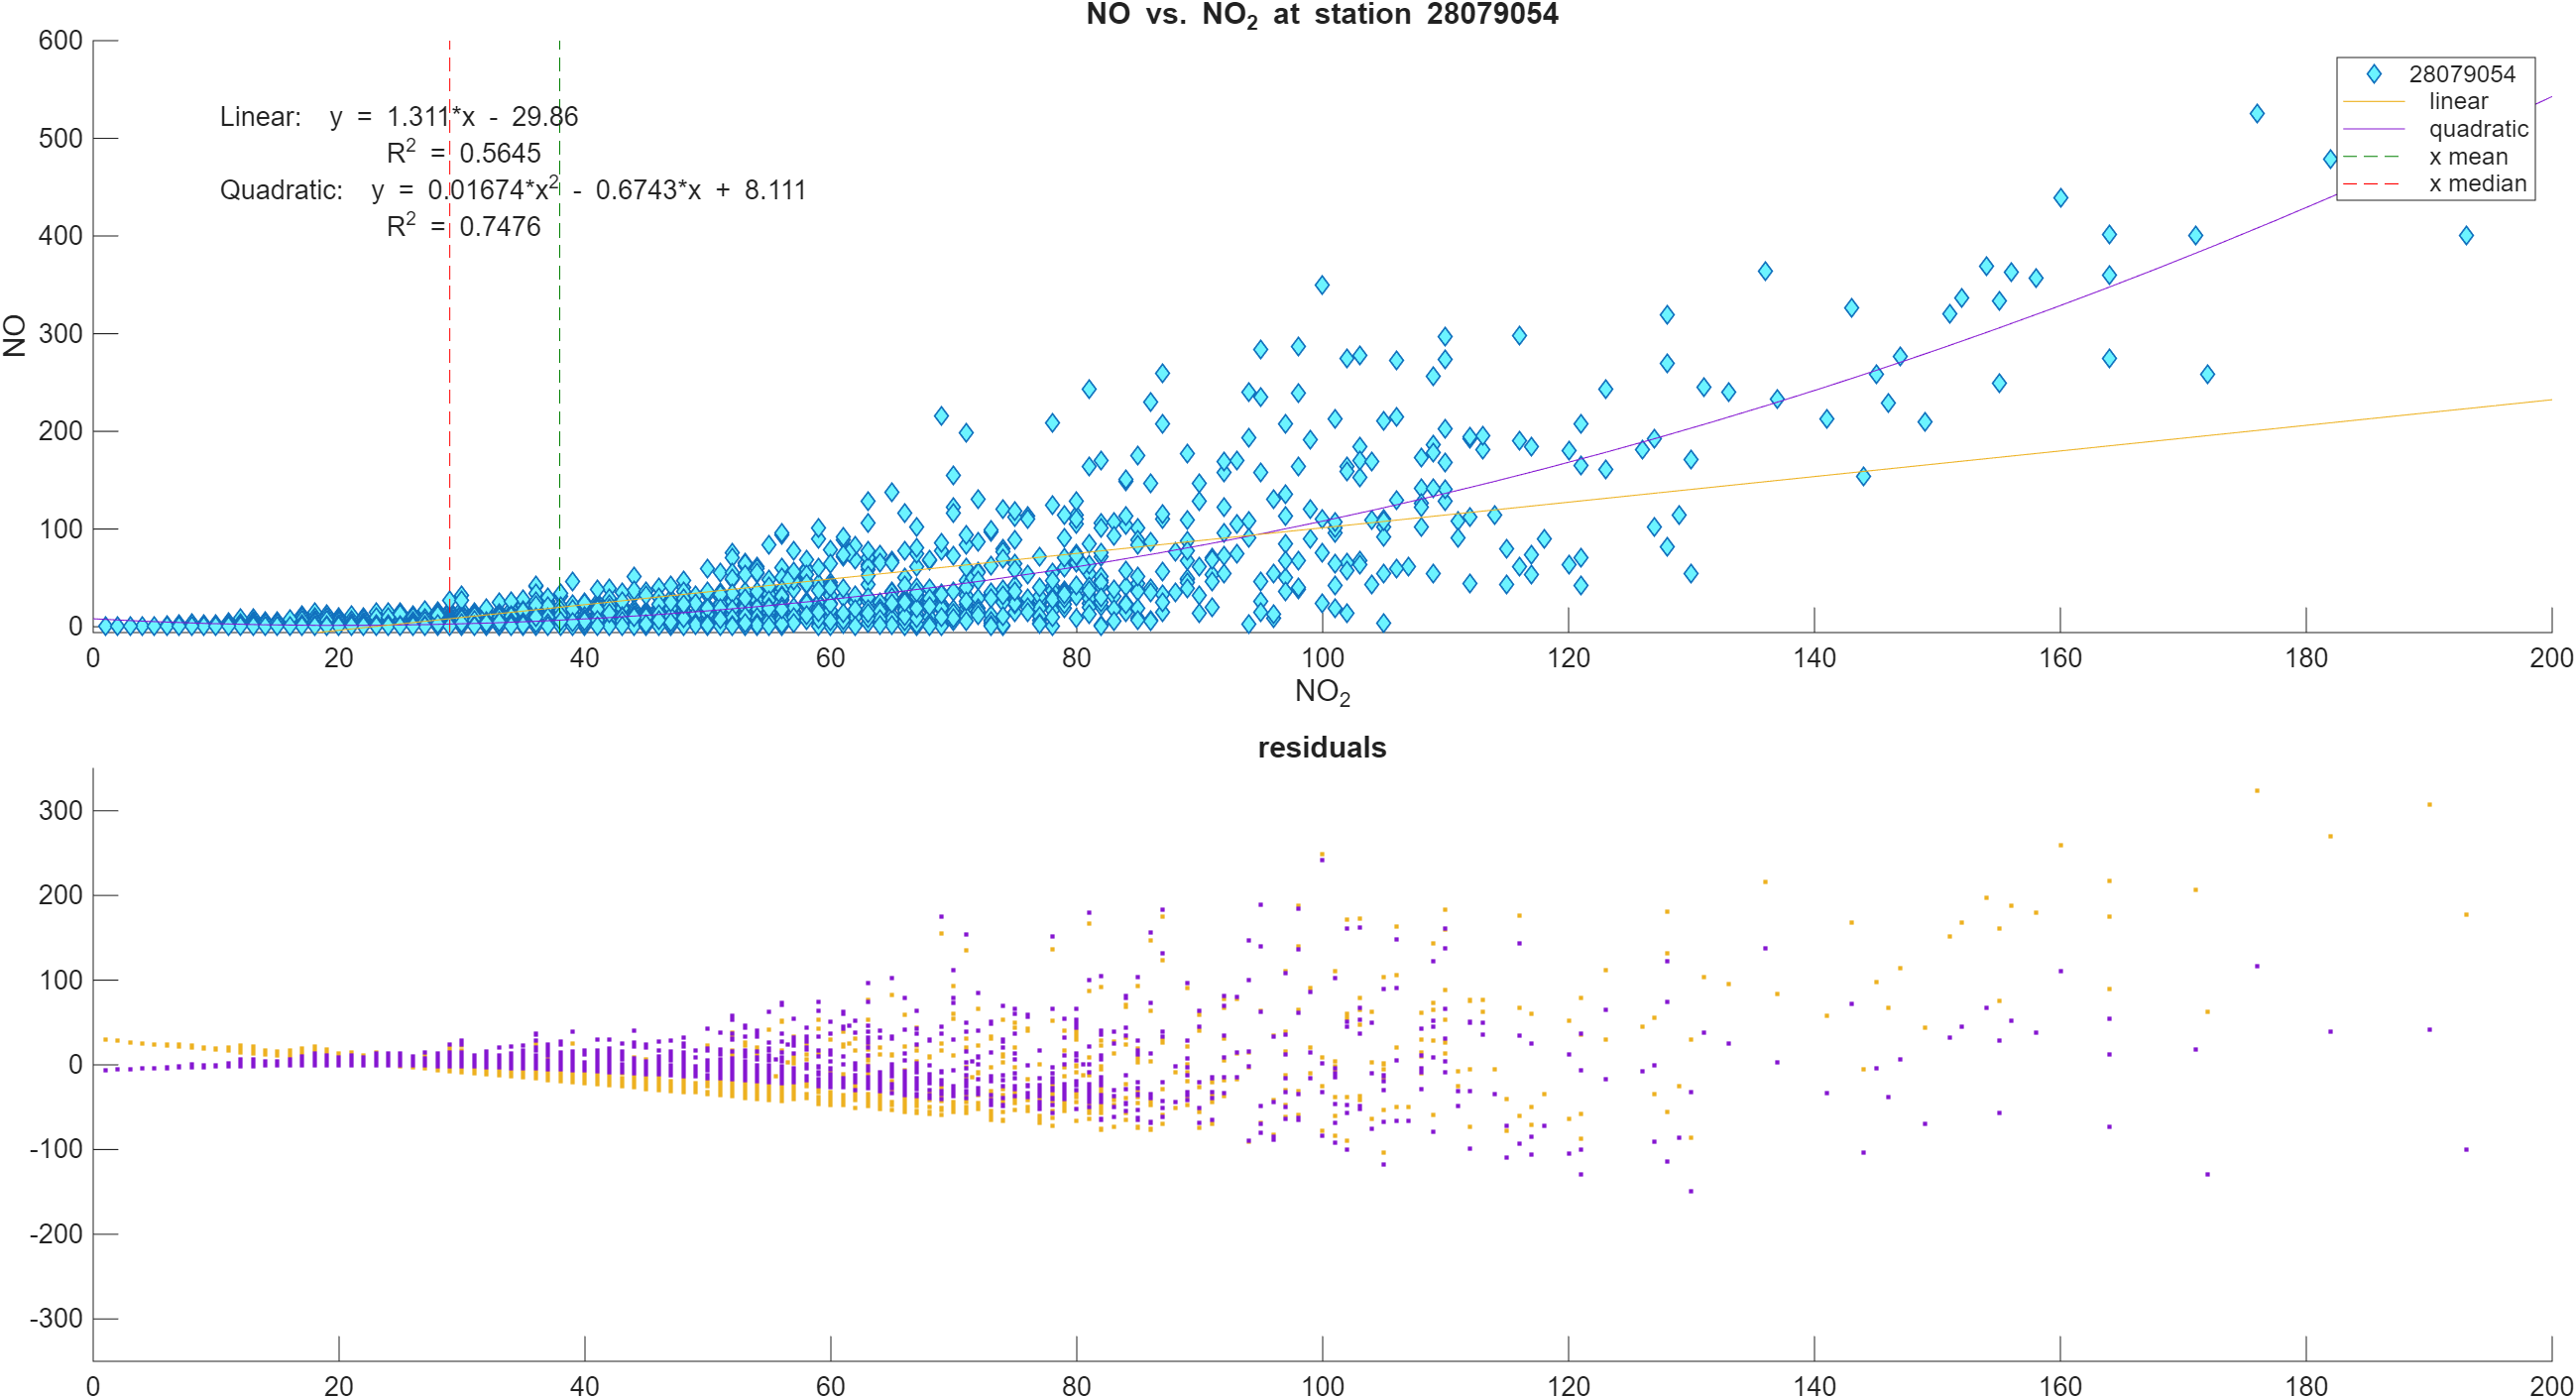

Author Kostas Leptokaropoulos

*"Copyright 2025, The MathWorks, Inc."*